clear;clc;close;

% Parameter
range = 5; lambda = 2; AOV = pi/6; alpha = AOV*0.5;
pos = [0;0]; perspective = [0;1]; perspective = perspective/norm(perspective);

range_max = ( (lambda+1)/lambda )*range*cos(alpha);
R = [cos(alpha) -sin(alpha);sin(alpha) cos(alpha)];

top = pos + range_max*perspective;
ltop = pos + range_max*( R*perspective );
rtop = pos + range_max*( (R')*perspective);

% Environment
L = 8; % length of the square
Wi = 8; % spacing between points

% Define the x and y ranges with a spacing of d
x_range = -L/2:0.01:L/2;
y_range = 0:0.01:Wi;

% Generate a grid of points within the x and y ranges
[X, Y] = meshgrid(x_range, y_range);

% Reshape the grid into a list of points
W = [X(:) Y(:)];

% Field of View
% Define the vertices of the triangle
A = [pos(1) pos(2)];
B = [ltop(1) ltop(2)];
C = [rtop(1) rtop(2)];

% Joint Probability
P0 = 0.8;
% P = @(d, a) 0.9*( ((d-range_max).^2).*((abs(a)-alpha).^2) )./( (range_max.^2).*(alpha.^2) );
P = @(d, W) ( ((W'-pos)./d)'*perspective  - cos(alpha) )/( 1 - cos(alpha) ).*...
    ( ( (vecnorm(W'-pos).^lambda).*( range*cos(alpha) - lambda.*( vecnorm(W'-pos) - range*cos(alpha) ) ) )./(range^(lambda+1)) )';

q_pers = @(d, W) ( ((W'-pos)./d)'*perspective  - cos(alpha) )/( 1 - cos(alpha) );
q_res = @(W) ( ( (vecnorm(W'-pos).^lambda).*( range*cos(alpha) - lambda.*( vecnorm(W'-pos) - range*cos(alpha) ) ) )./(range^(lambda+1)) );

P_ = @(d, a) P0.*exp( -((d-range_max).^2 )./(2*0.5^2) ).*exp( -((a-alpha).^2 )./(2*1.1^2) );

% Event Density
Sigma = [0.5 0; 0 0.5];

F1 = mvnpdf(W, [0.0, 6.8], Sigma)';
F2 = mvnpdf(W, [0.8, 4.5], Sigma)';
F3 = mvnpdf(W, [-0.8, 4.5], Sigma)';

% Probability of points in FOV
in_triangle = inpolygon(W(:,1), W(:,2), [A(1) B(1)+0.1 C(1)-0.1], [A(2)+0.1 B(2)-0.1 C(2)-0.1]);
% FOV = W(:,in_triangle);
d_W = vecnorm(W'-pos); index = find(d_W == 0); d_W(index) = 1;
a_W = acos( ((W'-pos)./d_W)'*perspective );

JP_Interior = P(d_W, W).*in_triangle;
JP_Boundary = P_(d_W, a_W').*in_triangle';

HW_Interior = sum(F1.*JP_Interior');% + sum(F2.*JP_Interior') + sum(F3.*JP_Interior'))*0.01^2;
HW_Boundary = (sum(F1.*JP_Boundary) + sum(F2.*JP_Boundary) + sum(F3.*JP_Boundary))*0.01^2;


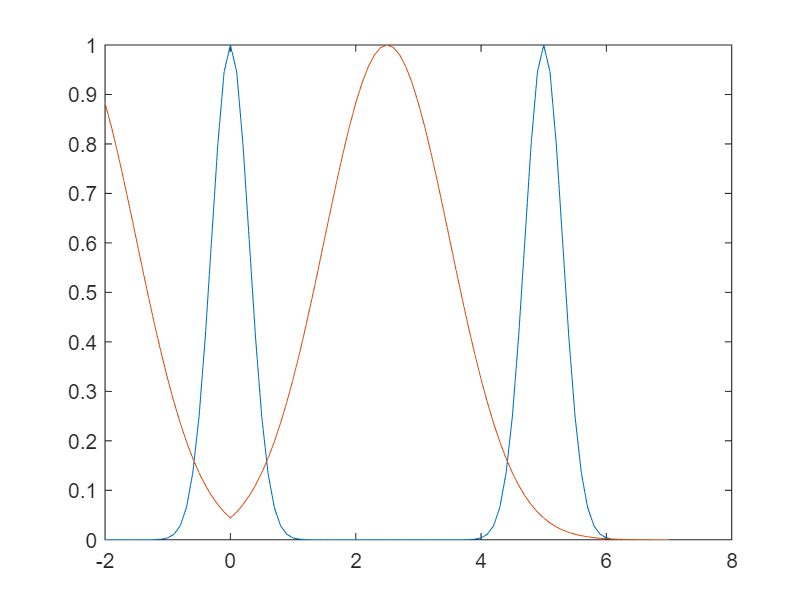

clear;clc;close;

mu = 2.5; x = -2:0.1:7;
sigma = 0.3;

y = exp( - ((abs(x-2.5)-mu).^2)./(2*sigma^2) );
y1 = exp( - ((abs(x)-mu).^2)./(2*1.0^2) );

plot(x, y, x, y1);